clear all;
close all;

L = [20 -4];
M = [6 5 1];
[A, b, c] = tf2ss(L,M);
[P, Q, w] = nyquist(L, M);
m1 = -0.225;
m2 = 0.21;

syms X Y
F = @(X,Y) 1-(m1+m2)*X+m1*m2*(X.^2+Y.^2);
WYNIK = eig(A)

WYNIK =    -0.5000
   -0.3333


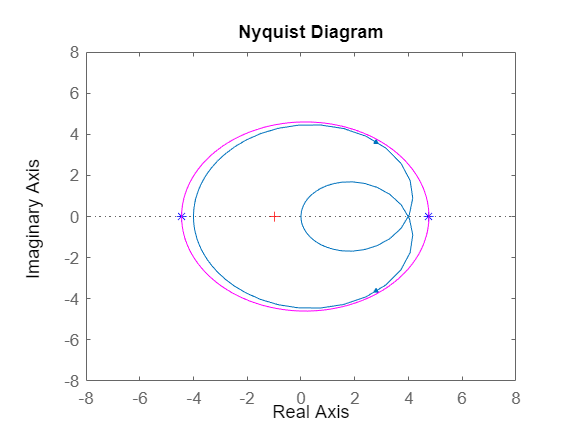

figure(1)
nyquist(L, M);
hold on
plot(1/m1, 0, 'b*');
plot(1/m2, 0, 'b*');
fcontour(F, 'm', 'LevelList', 0);
axis([-8 8 -8 8]);

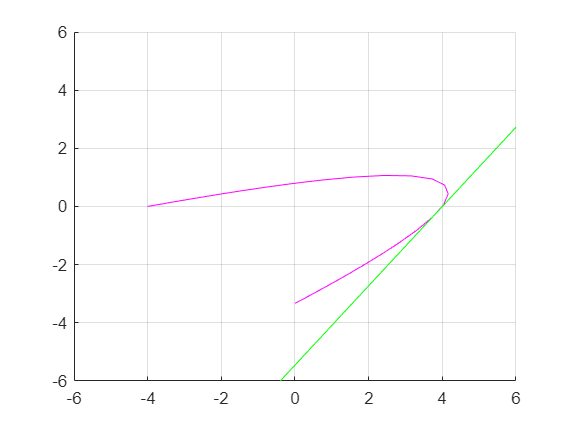

clear all;
close all;

L = [20 -4];
M = [6 5 1];
[A, b, c] = tf2ss(L,M);
WYNIK = eig(A);
[P, Q, w] = nyquist(L, M);
Q = w.*Q;

syms X Y
x1 = 4;
y1 = 0;
x2 = 3.726;
y2 = -0.3737;
q = (x1-x2)/(y1-y2);
m = 0.25;
F = X - q.*Y;
figure(1)
hold on
grid
plot(P, Q, 'm');
fcontour(F, 'g', 'LevelList', 1/m);
axis([-6 6 -6 6]);